# **Merge Git Branches and Resolve Conflicts Programmatically**

This example shows how to use the MATLAB® source control API to create and merge branches, and resolve conflicts.

## **Create New Git Repository**

Create a new Git™ repository in the current folder.

repo=gitinit();

## Add File to Repository

Create a `README.md` file and add it to the repository.

writelines("Questions?","README.md");
add(repo,"README.md");

Commit the file change.

commit(repo,Message="Add README file");

## Create Branches

Create two branches for your tasks.

Task1Branch = createBranch(repo,"Task1");
Task2Branch = createBranch(repo,"Task2");

## Modify Files on Branches

On the `Task1` branch, update the `README` file with the additional line "Contact example@mailinglist.com". Then, commit the change.

switchBranch(repo,"Task1");
writelines("Contact example@mailinglist.com","README.md",WriteMode="append");
commit(repo,Message="Modify README in Task1 branch");

On the `Task2` branch, update the `README` file with the additional line "Create an issue". Then, commit the change.

switchBranch(repo,"Task2");
writelines("Create an issue","README.md",WriteMode="append");
commit(repo,Message="Modify README in Task2 branch");

## Merge Branches

Merge the `Task1` branch into the `Task2` branch. The merge function reports that it cannot complete the merge due to a conflict in the `README` file.

try
   merge(repo,"Task1")
catch
     % The merge function throws an expected error because this branch merge
     % results in a conflict.
     fprintf("Unable to merge Task1 into Task2.\n\nCaused by:\n" + ...
         "Conflicted files: README.md\n\nResolve and " + ...
         "commit conflicted files to complete the merge.")
end

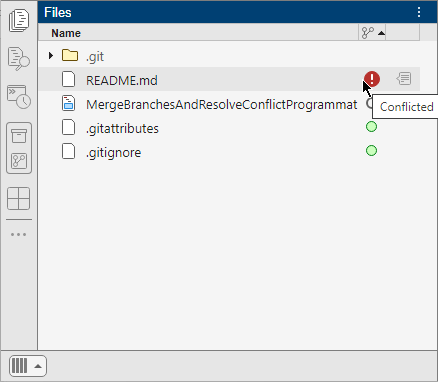

Open and inspect the content of the `README` file.

edit README.md

`Questions?`

`<<<<<<< HEAD`

`Create an issue`

`=======`

`Contact example@mailinglist.com`

`>>>>>>> ebc20d468cc6b8255130ccb2350b7d5db8d863f3`

## Resolve Conflict

Resolve the conflicts using the Comparison and Merge Tool or by editing the `README` file. For instructions on how to resolve the conflict interactively, see [Merge Text Files](docid:matlab_env#bt9l8o9-1). 

In this example, suppose you want to keep both changes. To keep both changes, simply delete the conflict markers.

writelines("Questions?","README.md");
writelines("Contact example@mailinglist.com","README.md",WriteMode="append");
writelines("Create an issue","README.md",WriteMode="append");

Mark the conflict in the `README` file resolved using the [add](docid:matlab_ref#mw_5924605c-cc62-4164-abc2-86e0ea104aad) function. Then, commit the merge resolution.

add(repo,"README.md")
commit(repo,Message="Resolve Conflict");

## See Also

[gitclone](docid:matlab_ref#mw_52o92940f3601b05-6c27-4c87-a88b-d859360bfcee) | [gitrepo](docid:matlab_ref#mw_536e3e301b05-6c27-4c87-a88b-d859360bfcee)  | [commit](docid:matlab_ref#mw_e84cb795-5217-42ab-a276-62e4914dbb73)  | [createBranch](docid:matlab_ref#mw_21dda80e-6e31-4fbb-95f6-4da470a4905b) | [switchBranch](docid:matlab_ref#mw_86f8c993-5e28-4ee4-8ea4-559e61bb1b57)  | [merge](docid:matlab_ref#mw_4bba02ab-9d18-489a-8455-f35ae45340a0) 

## Related Topics

[Set Up Git Source Control](docid:matlab_prog#bt523ej-1)

[Create, Manage, and Merge Git Branches](docid:matlab_prog#mw_b75ad6dd-8c81-48d3-be81-c660e60b3001)

## Related Examples

[Resolve Conflicts with Simulink Three-Way Merge](docid:simulink_ref.example-slxml_three_way_merge)

*Copyright 2023 The MathWorks, Inc.*